# Actin polymerization and physical models

# Part 2: Fitting to data

Matt Bovyn mbovyn@uci.edu

MCSB Bootcamp Dry 2019

So, we've investigated the behavior of our simple model for actin. Do we now understand how actin works in the cell? Probably not. However, if we could measure the lengths of a bunch of actin filaments, maybe we could tell if our model is sufficient to explain some simple case of actin behavior. For example, what if we measure the length of actin filaments assembled outside of the cell? We might learn if it just comes on and off in that situation. Maybe even how fast.

## Recap of results from our model exploration

From our exploration of the simple model we made, we should have learned several things.

- If $k_\text{on}>k_\text{off}$ the mean goes to infinity with increasing time. The distribution of lengths is Gaussian.

- For $k_\text{on}<k_\text{off}$ the mean is well defined and the distribution of lengths is exponential.

- For $k_\text{on}<k_\text{off}$ mean length is depends on the ratio of $k_\text{on}$ and $k_\text{off}$. We could probably have figured out the functional form given some time.

These things are handy for us because they make predictions about what we should see in experiments. What are they?

## Goals of this exercise

Here we want to examine some experimental data and learn how well our model fits the data. 

### What can we learn?

The first step of this does not involve data --- we need to figure out what we can learn first. As I mentioned in point 3 above, we probably could have figured out how the mean length depends on $k_\text{on}$ and $k_\text{off}$ with enough simulating and making plots. In this case, things are simple enough that you can write down some differential equations (you'll learn those tomorrow) and figure out the equation for the distribution. Let's cheat and take the answer from [http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html.](http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html.) It is:


$$P(\ell) =  \left(1 - {k_\text{on} \over k_\text{off}}\right)e^{-\ell \log (k_\text{off} / k_\text{on})}$$


Examine this equation. If we had data on the distribution, could we figure out $k_\text{on}$ and $k_\text{off}$?

The fact that we could replace ${k_\text{on} \over k_\text{off}}$ with another variable and not lose any information means that $k_\text{on}$ and $k_\text{off}$ themselves cannot be determined. Only their ratio can be. You might have learned in your simulations that multiple pairs of $k_\text{on}$ and $k_\text{off}$ could give you the same length distribution.

### The data

Now that we know what we can learn, what are we going to use to try to do it? We'll use experimental data on actin polymerized in vitro. We can examine a histogram of the data (if we want to lie to ourselves)

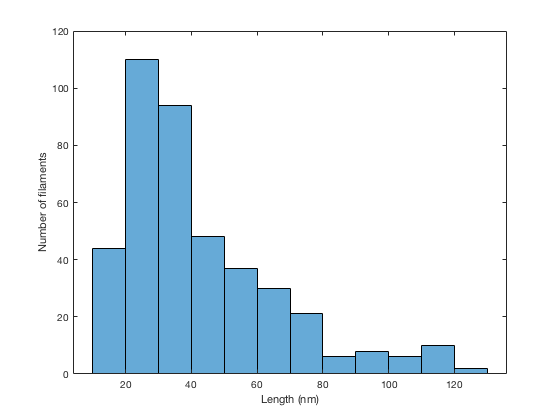

load('actin_lengths.mat')
histogram(sizes)
ylabel('Number of filaments')
xlabel('Length (nm)')

Or an ECDF (if we want to do things correctly).

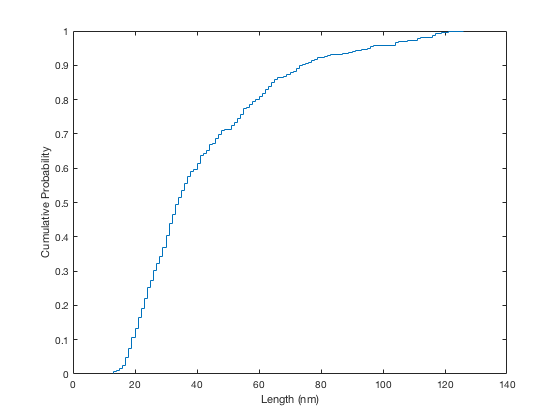

figure
[f,x]=ecdf(sizes);
stairs(x,f)
xlabel('Length (nm)')
ylabel('Cumulative Probability')

What do these distributions look like to you? Is it an exponential? Or is it peaked?

## Fitting functional forms

To get an idea what is going on, let's plot the data and put some distributions over it to compare.

Plot the data in a histogram and overlay probability density functions of an exponential distribution, a Weibull distribution, and a gamma distribution. Play around with the parameters of each distribution until you find a set for each that looks pretty close.

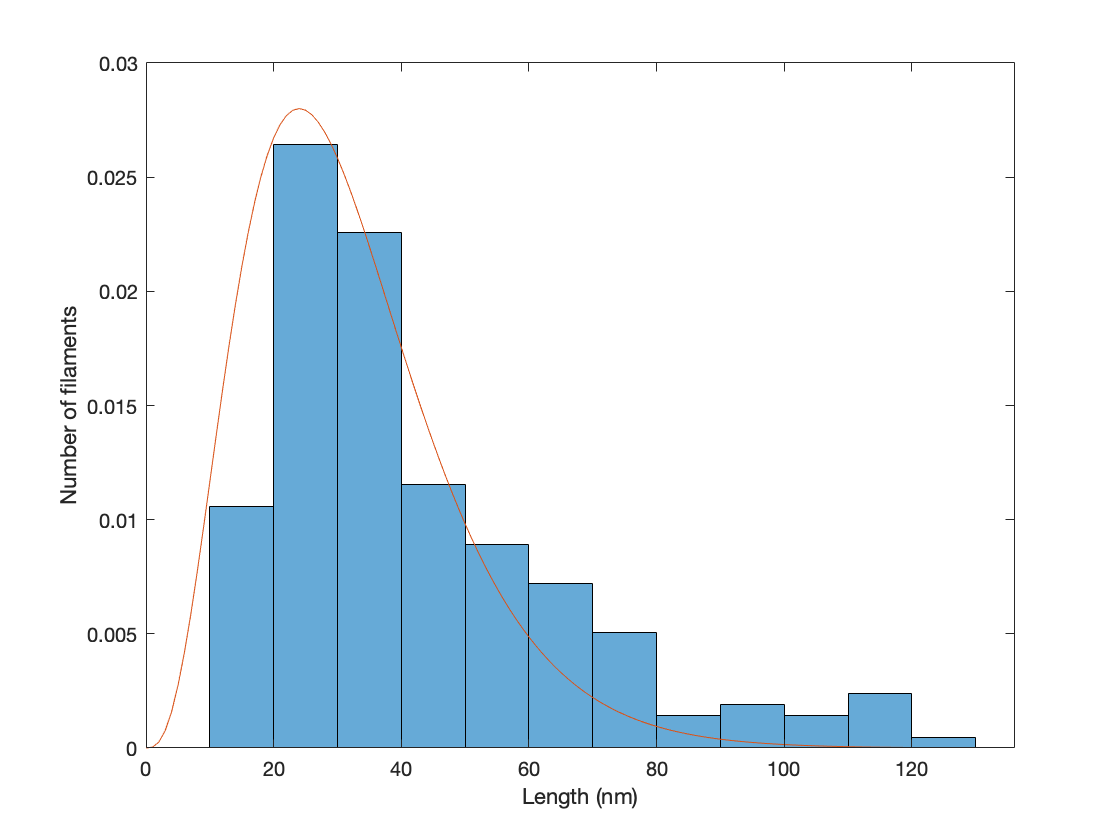

% your code here!

histogram(sizes,'Normalization','pdf')
ylabel('Number of filaments')
xlabel('Length (nm)')
hold on
plot(0:120,gampdf(0:120,4,8))
hold off

Now do the same for an ECDF of the data

% your code here!

#### Analyze

Which versions of these plots are easier to see how good the match is?

Play around with the number of bins in the histogram. Can you make one a fit look better or worse by changing the number of bins? Does ECDF have anthing you can change like this?

Which fits best?

## Fitting

By playing around with the parameters, you probably got the sense that there is likely a set that fits better the all the other ones. Matlab can find it for us. Let's look at how.

### Gamma Fit

Fit a gamma distribution to the ECDF. Use fminsearch(). There's an example here: [https://www.mathworks.com/help/matlab/math/example-curve-fitting-via-optimization.html](https://www.mathworks.com/help/matlab/math/example-curve-fitting-via-optimization.html)

I've provided you with a function to calculate the sum squared error (at the bottom of the script. You call it like this:

gamsse=@(params)sumsquarederrors(@gamcdf,params,sizes);
gamsse([4,5])

ans = 6.4642

Use it and fminsearch together to find the best fit parameters of the gamma distribution to the ECDF of the data. Plot that distribution.

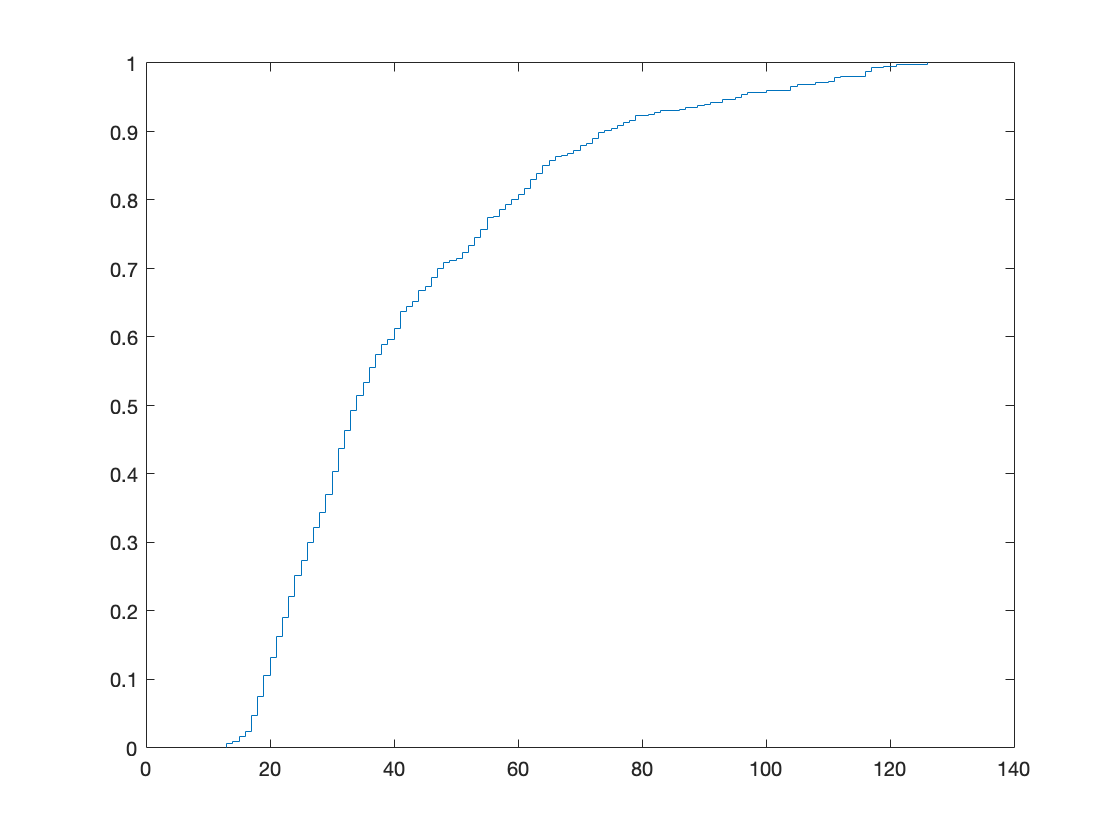

% your code here!

init=[5,1];
gamparams=fminsearch(gamsse,init);
stairs(x,f)

### Weibull Fit

Fit a Weibulll distribution to the ECDF the same way.

% your code here!

### Analysis

Does every pair of initial parameters give you the same fit?

Plot both fits together.

% your code here!

Which fit is better? What do we interpret from this? What do the output parameters mean about actin polymerization?

## Rethinking our interpretation

Let's learn how the data was generated. Read through the write up here:[http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html.](http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html.) 

Does this change your interpretation of the distribution of data we have? 

We have two possible interpretations:

- We can't see/discarded the data for short filaments. They exist, but aren't represented in our list of lengths.

- There aren't any short filaments. We should fit a peaked distribution like above

### Exponential fit

If we take the first interpretation, how do we fit an exponential distribution to data we don't have? Let's try two ways: Fitting to the histogram data and to the ECDF. 

#### Fit to Histogram

This looks sort of like a good fit if you only look at data for >nm, right?

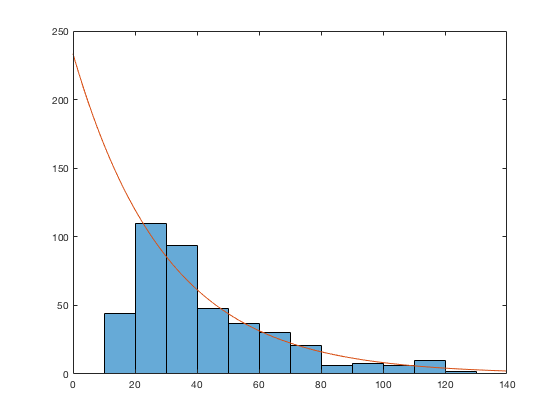

histogram(sizes)
hold on
multiplier=7000;
mu=30;
plot(0:140,multiplier*exppdf(0:140,mu))
hold off

Fit to the data from the histogram for >20nm. Your fit parameters are the multiplier and the mean, mu.

#### Fit to ECDF

This looks pretty good too, for >20nm

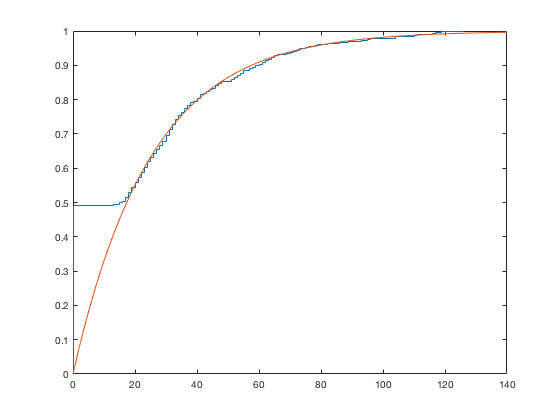

[f,x]=ecdf([sizes zeros(1,400)]);
stairs(x,f)
hold on
plot(0:140,expcdf(0:140,25))
hold off

Fit to the ECDF. Fit parameters are the number of missing data points and the mean

## Analyze

Are these two methods doing different things? Which one is better?

## Conclusion

We learn a valuable lesson here. Fitting a model to data is an exercise of interpretation. The way the data was generated makes a big difference in that interpretation!

function sse = sumsquarederrors(fun,params,sizes)

    [f,x]=ecdf(sizes);
    
    y=fun(x,params(1),params(2));
    
    sse=sum((y-f).^2);

end